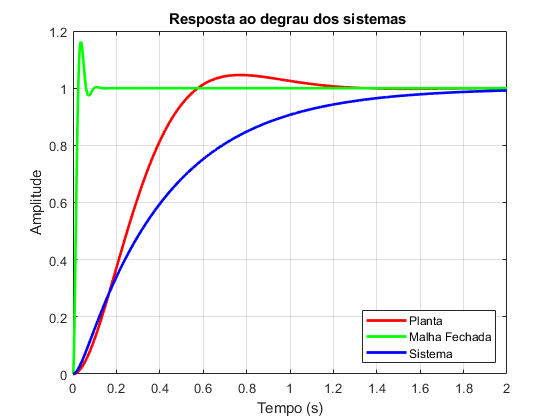

% Parâmetros do sistema
Kp = 24.47; % Ganho proporcional
Ki = 99.84; % Ganho integral
Kd = 3.06; % Ganho derivativo

% Tempo de simulação
t = 0:0.001:2;

% Função de transferência da planta
num = 32.65;
den = [1 8 32.65];
plant = tf(num, den);

% Função de transferência do sistema
num = 83.2;
den = [1 36.44 83.2];
plant2 = tf(num, den);

% Controlador PID
pidController = tf([Kd Kp Ki], [0.01 1 0]); % Criando o controlador PID

% Sistema em malha fechada
sys = feedback(pidController*plant, 1);

% Simulação dos dois sistemas
y1 = step(plant, t);
y2 = step(sys, t);
y3 = step(plant2,t);

% Plot dos resultados
plot(t, y1, 'r', 'LineWidth', 2);
hold on;
plot(t, y2, 'g', 'LineWidth', 2);
hold on;
plot(t, y3, 'b', 'LineWidth', 2);
hold off;

% Configurações do gráfico
title('Resposta ao degrau dos sistemas ');
xlabel('Tempo (s)');
ylabel('Amplitude');
legend('Planta', 'Malha Fechada','Sistema','Location', 'southeast');
grid on;